# 'coneplot' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create scene

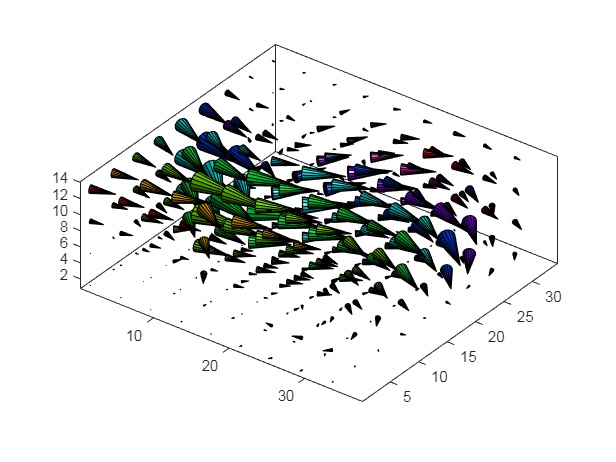

pl.scene_begin('scene_file', 'coneplot.pov', 'image_file', 'coneplot.png');
pl.include("textures");
pl.include("glass");
pl.include("golds");

pl.global_settings("assumed_gamma 1");

% Camera
% type: perspective | orthographic | mesh_camera{MESHCAM_MODIFIERS} | fisheye | ultra_wide_angle |
%       omnimax | panoramic | cylinder CylinderType (<int[1..4]>) | spherical

% Streamline
%pl.camera('angle', 35, 'location', [120 120 80], 'look_at', [110 40 0], 'type', 'perspective');

% Coneplot (+/-)
pl.camera('angle', 35, 'location', [50 50 30], 'look_at', [0 1 0]);

% pl.camera('location', [12 12 12], 'look_at', [0 1 0]);
% pl.camera('angle', 35, 'look_at', [0 1 0]);
% pl.camera("angle", 15, 'location', [12 12 12]);

% pl.light();
pl.light('location', [70 70 20], 'color', [0.9 0.9 0.9], 'shadowless', true);
pl.light('location', [70 70 -20], 'color', [0.9 0.9 0.9], 'shadowless', true);
pl.light('location', [2 2 2], 'color', [0.9 0.9 0.9], 'shadowless', true);
% pl.light('location', [100 200 300], 'color', [0.4 0.4 0.4], 'shadowless', true);

% pl.light('location', [100 0 0], 'color', [0.1 0.1 0.1]);
% pl.light('location', [0 100 0], 'color', [0.1 0.1 0.1]);
% pl.light('location', [0 0 100], 'color', [0.1 0.1 0.1]);

% Axis textures
tex_axis_odd = pl.declare("tex_axis_odd", pl.texture('pigment', [0.5 0.5 0.5], "finish", "phong 1 reflection {0.10 metallic 0.4}"));
tex_axis_even = pl.declare("tex_axis_even", pl.texture('pigment', [1 1 0], "finish", "phong 1 reflection {0.10 metallic 0.4}"));
%tex_axis_y = pl.declare("tex_axis_y", pl.texture('pigment', [0 1 0], "finish", "phong 1 reflection {0.10 metallic 0.4}"));
% tex_axis_z = pl.declare("tex_axis_z", pl.texture([0 0 1], "phong 1 reflection {0.10 metallic 0.4}"));

% Axis
% pl.axis();
% pl.axis('length', [5 6 7], 'tex_common', pl.tex_axis_x, 'tex_x', pl.tex_axis_z);
pl.axis('length', [50 50 50], 'radius', 0.3, 'tex_common', tex_axis_odd, 'tex_x', tex_axis_even, 'tex_y', tex_axis_even, 'tex_z', tex_axis_even);

% Axis planes textures
% tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.8 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.8 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.8], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));

tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));

% Axis planes
% pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_plane_red',  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
% pl.plane('normal', [0,1,0], 'distance', 0, 'texture', tex_plane_green, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
% pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane_blue,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);

% Grid
% tex_grid_gray  = pl.declare("tex_grid_gray",  pl.texture('pigment', [0.5 0.5 0.5], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_grid_red   = pl.declare("tex_grid_red",   pl.texture('pigment', [1.0 0.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_grid_green = pl.declare("tex_grid_green", pl.texture('pigment', [0.0 1.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_grid_blue  = pl.declare("tex_grid_blue",  pl.texture('pigment', [0.0 0.0 1.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));

% pl.grid_2D('width', 10, 'height', 10,                      'translate', [5 0 5], 'texture_odd', tex_grid_green, 'texture_even', tex_grid_gray);
% pl.grid_2D('width', 10, 'height', 10, 'rotate', [ 0 0 90], 'translate', [0 5 5], 'texture_odd', tex_grid_blue,  'texture_even', tex_grid_gray);
% pl.grid_2D('width', 10, 'height', 10, 'rotate', [90 0  0], 'translate', [5 5 0], 'texture_odd', tex_grid_red,   'texture_even', tex_grid_gray);

% pl.grid('width', 10, 'height', 10, 'radius', 0.01,                     'translate', [5 0 5]);
% pl.grid('width', 10, 'height', 10, 'radius', 0.01,'rotate', [ 0 0 90], 'translate', [0 5 5]);
% pl.grid('width', 10, 'height', 10, 'radius', 0.01,'rotate', [90 0  0], 'translate', [5 5 0]);

% Objects textures
% tex_red   = pl.declare("tex_red",   pl.texture('pigment', [1 0 0], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
% tex_green = pl.declare("tex_green", pl.texture('pigment', [0 1 0], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
% tex_blue  = pl.declare("tex_blue",  pl.texture('pigment', [0 0 1], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
% tex_pink  = pl.declare("tex_pink",  pl.texture('pigment', [8 2 3], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));

% pl.coneplot_material();
% pl.coneplot_material('finish', 'Metal', 'interior', 'ior 1.1', 'alpha', 0.3);
% pl.coneplot_material('finish', 'crand 0.01', 'interior', 'I_Glass', 'alpha', 1.0);
% pl.coneplot_material('finish', 'Glossy', 'interior', 'ior 1.5', 'alpha', 0.3);
% https://se.mathworks.com/help/matlab/ref/surf2patch.html

% Patch
%
% t = 0:pi/5:2*pi;
% figure
% h = patch(sin(t) * 10, cos(t) * 10,'y')

% Surface
% s = surf(peaks);
% [X,Y] = meshgrid(1:0.1:40, 1:0.1:40);
% Z = sin(X) + cos(Y);
% s = surf(X,Y,Z)
% pl.surface2('data', s);

% [X,Y] = meshgrid(-10:.1:10);
% Z = Y.*sin(X / 2) - X.*cos(Y / 3);
% s = surf(X,Y,Z,'FaceAlpha',0.5)
% pl.surface2('data', s);

% Wind for streams
load wind u v w x y z
[m,n,p] = size(u);
m = 35;
n = 41;
p = 15;
[~,n,p] = size(u);

% Streamtube
% [Sx, Sy, Sz] = meshgrid(1,1:5:n,1:5:p);
% st = streamtube(u,v,w,Sx,Sy,Sz);
% pl.streamtube('data', st);

% Coneplot
[Cx, Cy, Cz] = meshgrid(1:4:m,1:4:n,1:4:p);
cp = coneplot(u,v,w,Cx,Cy,Cz,y,5);
pl.coneplot('data', cp);

axis tight equal
view(37,32)
box on
colormap(hsv)
light

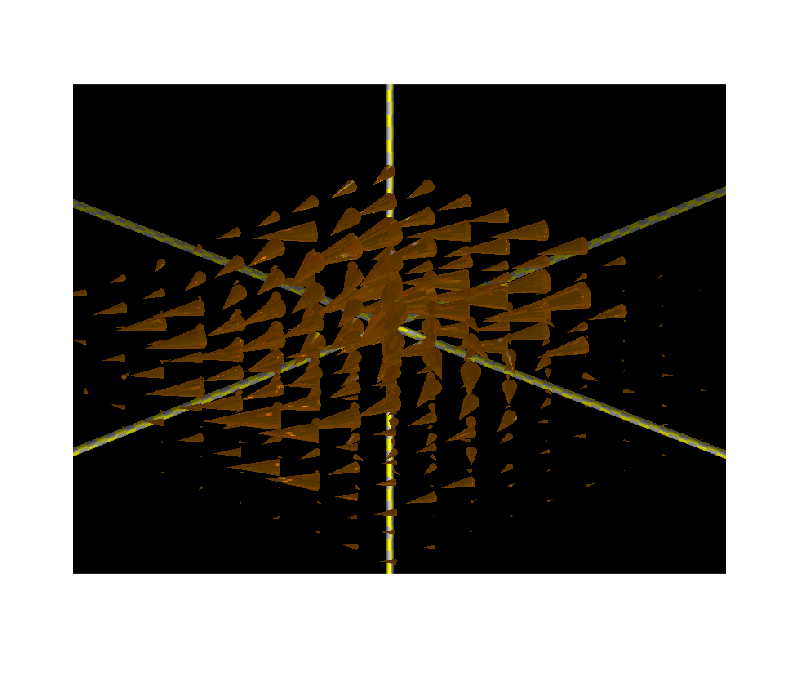


pl.scene_end();
% TODO: Allow afer writing to scene in pov_coneplot
img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 4.361274 seconds.
